# Import Dates and Times from Text Files

Import formatted dates and times (such as `'01/01/01'` or `'12:30:45'`) from column oriented tabular data in three ways.

- Import Tool — Interactively select and import dates and times.

- `readtable` function —  Automatically detect variables with dates and times and import them into a table.

- Import Options —  Use` readtable` with `detectImportOptions` function for more control over importing date and time variables. For example, you can specify properties such as `FillValue` and `DatetimeFormat`. 

This example shows you how to import dates and times from text files using each of these methods.

## Import Tool

Open the file `outages.csv` using the Import Tool. Specify the formats of dates and times using the drop-down menu for each column. You can select from a predefined date format, or enter a custom format. To import the `OutageTime` column, specify the custom format `yyyy-MM-dd HH:mm`. Then, click the **Import Selection** button to import the data into the workspace.

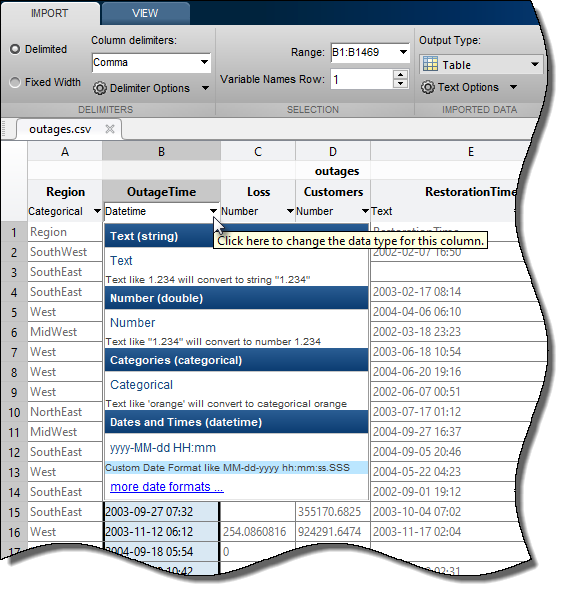

## `readtable` Function

Use the `readtable` function and display `10` rows of the `OutageTime` variable. `readtable `automatically detects the date time variables and formats. 

filename = 'outages.csv';
T = readtable(filename);
T.OutageTime(1:10)

## Import Options

Use an import options object for more control over importing date and time variables. For example, change the date-time display format or specify a fill value for missing dates. 

Create an import options object for the `outages.csv` file and display the variable import options for the variable `RestorationTime`. The `detectImportOptions` function automatically detects the data types of the variables.

opts = detectImportOptions(filename);
getvaropts(opts,'RestorationTime')

Import the data and display the first `10` rows of the variable `RestorationTime`. The second row contains a `NaT`, indicating a missing date and time value.

T = readtable(filename,opts);
T.RestorationTime(1:10)   

To use a different date-time display format, update the `DatetimeFormat` property, and then replace missing values with the current date and time by using the `FillValue` property. Display the updated variable options. 

opts = setvaropts(opts,'RestorationTime', ...
                       'DatetimeFormat','MMMM d, yyyy HH:mm:ss Z',...
                       'FillValue','now');
getvaropts(opts,'RestorationTime')

Read the data with the updated import options and display the first `10` rows of the variable.

T = readtable(filename,opts);
T.RestorationTime(1:10)   

For more information on the `datetime` variable options, see the `setvaropts` reference page.

*Copyright 2018 The MathWorks, Inc.*